# Lie algebra rotation

close all;
clear;
clc;

## read model

TR = stlread("cube.stl");

model.Vertices = TR.Points;
model.Faces = TR.ConnectivityList;

xaxis = [[0,0,0]', [2,0,0]'];
yaxis = [[0,0,0]', [0,2,0]'];
zaxis = [[0,0,0]', [0,0,2]'];

vertices_base = model.Vertices';

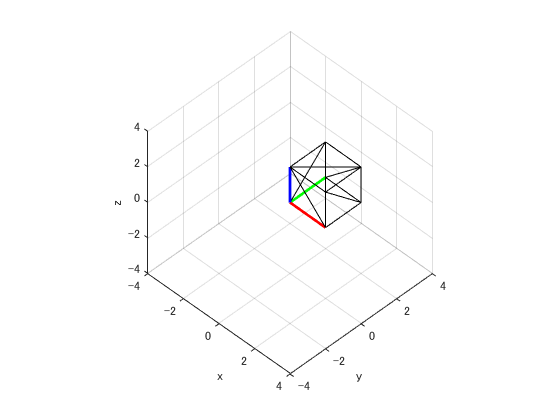

figure;
axis equal;
grid on;
hold on;

patch(model, 'FaceColor', 'none');
plot3(xaxis(1,:), xaxis(2,:), xaxis(3,:), 'Color', 'red', 'LineWidth', 2);
plot3(yaxis(1,:), yaxis(2,:), yaxis(3,:), 'Color', 'green', 'LineWidth', 2);
plot3(zaxis(1,:), zaxis(2,:), zaxis(3,:), 'Color', 'blue', 'LineWidth', 2);

% ranges
xlim([-4, 4]);
ylim([-4, 4]);
zlim([-4, 4]);

% labels
xlabel("x");
ylabel("y");
zlabel("z");

% view angle
view([45, 45]);

## rotate model

Interpolates poses between RPY(0, 0, 0) and RPY(r, p, y), where RPY is defined as the roll-pitch-yaw rotation matrix in SO(3).

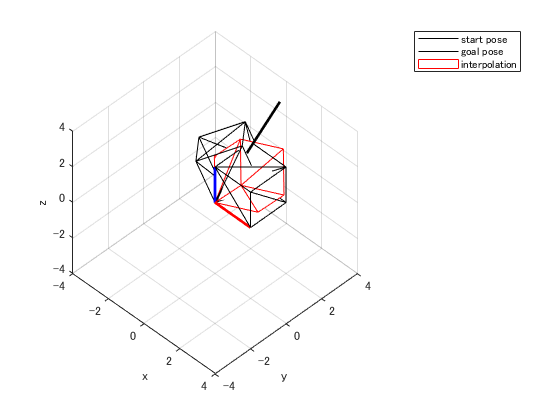

r = 1.162355;
p = 0.282735;
y = 2.293295;

% division
N = 101;
n = 48;
n = n + 1;

figure;
axis equal;
grid on;
hold on;

% ranges
xlim([-4, 4]);
ylim([-4, 4]);
zlim([-4, 4]);

% labels
xlabel("x");
ylabel("y");
zlabel("z");

% view angle
view([45, 45]);

% start pose
vertices = vertices_base;
model.Vertices = vertices';
patch(model, 'EdgeColor', 'black', 'FaceColor', 'none');

% goal pose (defined with roll-pitch-yaw)
vertices = yaw(y) * pitch(p) * roll(r) * vertices_base;
model.Vertices = vertices';
patch(model, 'EdgeColor', 'black', 'FaceColor', 'none');

% linear interpolation with Lie algebra
Xs = logm(eye(3));                      % SO(3) -> so(3)
Xg = logm(yaw(y) * pitch(p) * roll(r)); % SO(3) -> so(3)
xs = vee3(Xs);                          % R^3
xg = vee3(Xg);                          % R^3
x = [
    linspace(xs(1), xg(1), N);
    linspace(xs(2), xg(2), N);
    linspace(xs(3), xg(3), N);
    ];

X = wedge3(x(:,n));
R = expm(X);
vertices = R * vertices_base;
model.Vertices = vertices';
patch(model, 'EdgeColor', 'red', 'FaceColor', 'white');

% axes
plot3(xaxis(1,:), xaxis(2,:), xaxis(3,:), 'Color', 'red', 'LineWidth', 2);
plot3(yaxis(1,:), yaxis(2,:), yaxis(3,:), 'Color', 'green', 'LineWidth', 2);
plot3(zaxis(1,:), zaxis(2,:), zaxis(3,:), 'Color', 'blue', 'LineWidth', 2);
xx = 10*vee3(Xg - Xs);
plot3([0,xx(1)], [0,xx(2)], [0,xx(3)], 'Color', 'black', 'LineWidth', 2);

legend(["start pose", "goal pose", "interpolation"])